# LECTURE WEEK VII. - EXERCISE

# SIGNAL PROCESSING IN ACTION

**Objectives:**

- Experience the used of spectra/DFT in existing computer science applications.

- Learn how to extract relevant features from spectra/DFTs.

- Introduction to perceptual aspects of signal processing.

This MATLAB Exercise will be introduced and solved during the working group. Its approach for instance framing and windowing of signals and computing the spectrogram strongly relates to the MATLAB Assignments ***VII.1*** and ***VII.2***. Therefore, active participation in solving this exercise will make completing the MATLAB Assignments much easier.

## MATLAB Exercise VII.1: MFCCs - Towards automated speech recognision

Automated speech recognition, or ASR, deals with the problem of automatically recognizing spoken language. Research in ASR has produced well-­consolidated technology based on Hidden Markov Models (HMMs). In its most general formulation, the ASR problem consists of finding the sequence of words associated with a given (recorded) acoustic signal. Approaches to ASR usually follow a multi-­level model. At the first level, the acoustic signal is condensed and characterized by signal features related to the human phonetic system, called *phonemes*. Phonemes are the most basic unit of sound in speech. The next level associates strings of phonemes to form words. The third level considers possible words in relation to each other so as to form phrases and utterances. HMMs integrate the levels so that they are all processed simultaneously.

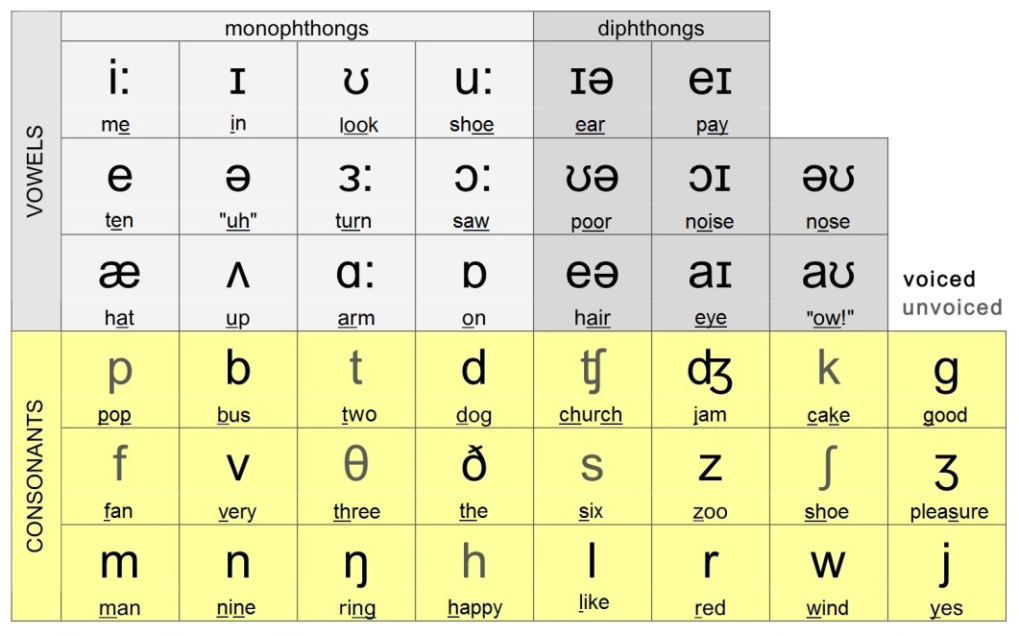

In this assignment we focus on the first level, namely computing phonemes. We will investigate the conversion of the speech signal into speech features order to understand the ability of speech features to represent the similar and differences between phonemes. The diagram below shows a phonetic chart for the English language. Similar phonetic charts exist for different languages.

In ASR, phonemes are characterized by a set of numbers – referred to as features of the speech signal. The features used by most speech recognizers are MFCCs or “*Mel Frequency Cepstral Coefficients*”. The idea is that each phoneme has a distinctive set of MFCCs, hence recognizing a phoneme can – in principle –be done based on the computed MFCCs of a frame of speech. In practice, the MFCCs associated with a given phoneme are far from unique. Different recordings of the same phonemes can differ from each other due to noise, echoes, speech speed, speaker dialect, and other acoustic phenomena. The other levels of processing used by HMMs (exploiting statistics of words and language) help to resolve inherent ambiguity in the estimated phonemes/MFCCs.

We will compute MFCCs from speech signals, and find out how single phonemes can be distinguished based on the computed MFCCs.

***A.***

Read the sample speech file “`data/phonemesraam.wav`” into MATLAB, plot the speech signal, and listen to the speech. Speech recognition typically works with speech frames of 20-­40 msec. We use frames of length 512 samples. 

***Answer:***

How many milliseconds are the speech frames in this case? 

***Answer:***

***B.***

Before splitting the speech signal into frames, it is usually high-­pass filtered as so to relatively enhance the higher frequencies in the signal. Apply a high-­pass FIR filter to the speech signal with impulse response $h[n] = \delta[n] - 0.95 \delta[n-1]$

***Answer:***

***C.***

The speech signal is subdivided into non-­overlapping frames of length **512** samples. We put the frames of N samples into a matrix `XX(n,m)` of $N$ rows by $M$ columns ($N=512$, $M$ depends on the length of the speech signal). Each column then contains a frame of **512** samples. Details of this conversion process are part of the MATLAB HANDS-­ON Assignment **VII.1*****A*** and ***VII.1B***.

***Answer:***

***D.***

The speech recognition process is relatively sensitive to noise that exists in silent intervals when no speech occurs. We therefore make the signal equal to zero in all frames that do not contain speech. Compute for each frame the variance (for instance for the 7th frame use the command `var(XX(:,7))` ). If the variance is smaller than a threshold $T$, make the signal in the corresponding frame equal to zero. Find a suitable threshold, and plot the result using the command `plot(XX(:))` to make sure that you only eliminated silences and not the speech signal.

***Answer:***

Rather than using the frames directly, they are multiplied by a so-­called Hamming window of length **512**. The purpose of multiplying each frame with a window is to avoid the unnatural **60** discontinuities between head and tail of the frame due to the circular extension effects when using DFTs/FFTs. The Hamming window is defined as follows:


$$w[n] = 0.54 - 0.46\cos\Big(\frac{2\pi n}{N-1}\Big) \quad n=0,\dots,N-1$$


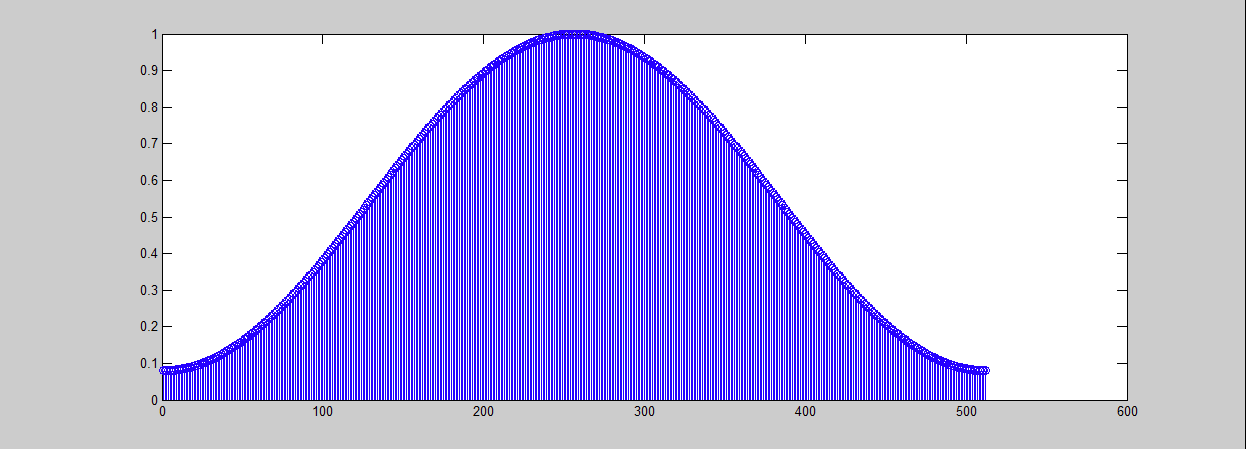

***E.***

Implement the Hamming window and multiply each frame (column) in the matrix `XX(n,m)` with the Hamming window. Then carry out the DFT on each of the frames, and compute the square of the magnitude of each DFT coefficient. Display the result (or the log of the result for better visualization) using the pseudo-­color command `pcolor()`.

***Answer:***

The MFCCs are computed based on perceptual weighting using logarithmic frequency band, in this case according to the Mel frequency-­scale. To obtain a 24-­band *Mel frequency-scale*, the first 257 (unique) DFT coefficients of a 512-­point DFT are combined in the following way.

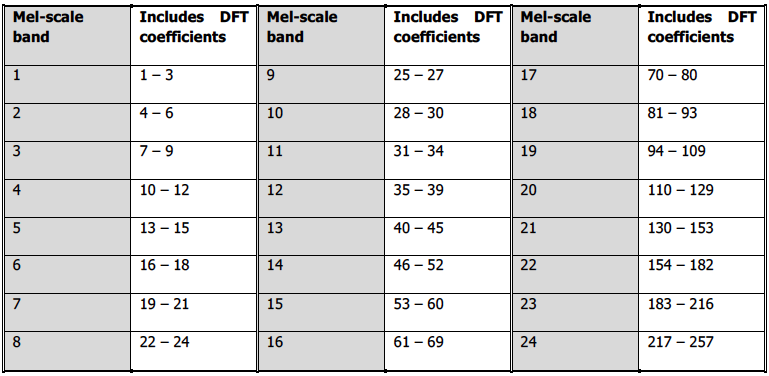

***F.***

The above mapping from DFT coefficient number to Mel frequency-­scale is available in the MATLAB matrix ‘`data/mel_scale_band_id.ma`t’. Load this matrix using the command `load mel_scale_band_id.mat`, and inspect the relation of the loaded matrix `MelScaleBandID` to the above table

***Answer:***

***G.***

For each frame, add the square of the magnitude of the DFT coefficients (computed in part ***E.***) that belong to the same Mel frequency-­scale band, yielding a matrix with for each frame **24** values. These values are called *Mel frequency-­scale energies*. Make use of the matrix `MelScaleBandID` loaded in part (f). Store the resulting 24x$M$ Mel frequency-scale energies as the matrix `MM`.

The final ‘Mel Frequency Cepstral Coefficients’ (MFCCs) are obtained by taking the inverse *discrete cosine transform *(DCT) of the logarithm of the Mel frequency-­scale energies computed in part ***F***. The DCT is a transform similar to the DFT, except for the fact that it does not yield complex-­valued coefficients. The inverse DCT is available in MATLAB as the command `idct`.

***H.*** 

Compute the inverse DCT of the logarithm of the matrix `MM` that stores the 24x$M$ Mel frequency-­scale energies, for instance for the $3^{rd}$ frame in the matrix `MM` use the command:

***Answer:***

The columns of the resulting matrix `MFCC` now contain the **24** MFCCs per frame. Display the result using the pseudo-­color command `pcolor()`. The figure below shows an example of such matrix containing the MFCCs for four different phonemes. Horizontally is the frame index, vertically are the computed MFCCs.

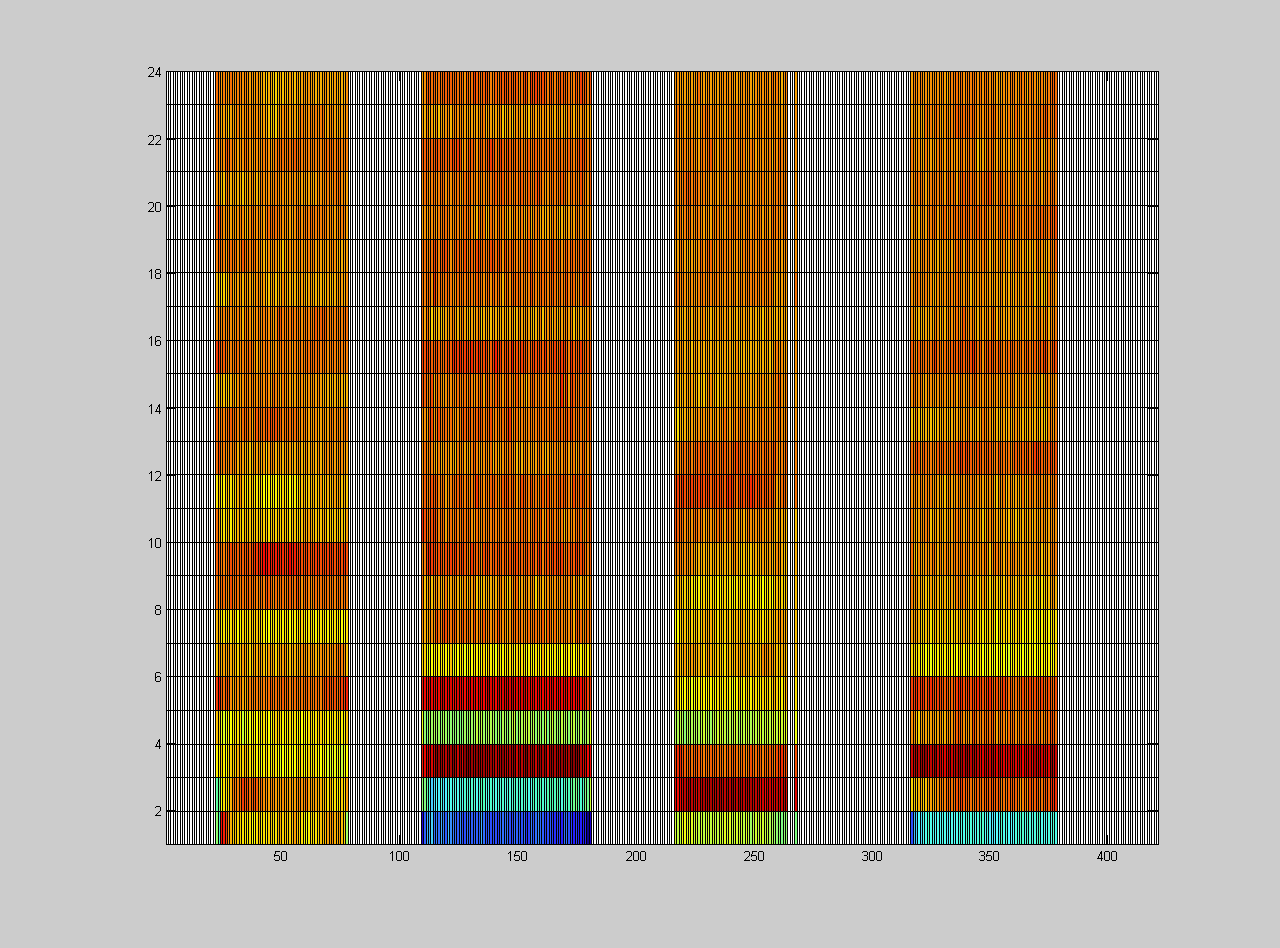

In ASR, the first 8 to 12 computed MFCCs are then used in recognizing series of phonemes (words and phrases) through Hidden Markov Model estimation. HMMs are able to capture the way that the speech signal changes over time. Your visualization of the MFCCs should already suggest to you that a single phoneme is not static over time. In fact, as a phoneme is being pronounced, the feature vector can only be expected to be stable for approximately 10ms. For this reason, HMMs usually using overlapping frames and also decompose a phoneme into parts, e.g., a beginning, a middle, and an end. The theory and application of HMMs is outside the scope of the course Signal Processing, and relies strongly on random processes and pattern recognition theory.

Visualizing the ability for MFCCs to distinguish between phonemes is not easy since the MFCCs are vectors in a high-­dimensional space. Nevertheless, to get a feeling for how well the MFCCs can distinguish the different phonemes, we visualize the first four MFCCs for the frames in the speech signal.

As an example, the four figures below show X-­Y scatter plots of the MFCC. In figure (a), the first two MFCC of all frames are plotted for a speech signal containing the vowels of the word “raam”. For every frame, horizontally the first MFCC is plotted and vertically the second MFCC. In figure (b) the third and fourth MFCCs are plotted. From these two scatter plots we see that if the phonemes are clearly pronounced, the MFCCs of each phoneme end up in clusters. Figures (c) and (d) show scatter plots of the first & second, and third & fourth MFCC, respectively, obtained from the pronounced word “raam”. It is clear that although the MFCCs of the phonemes can be recognized in these scatter plots, the recognition of the word “raam” from the MFCCs indeed requires a lot of further processing.

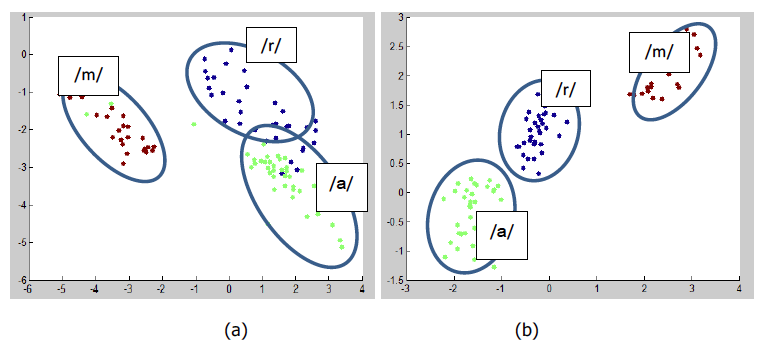

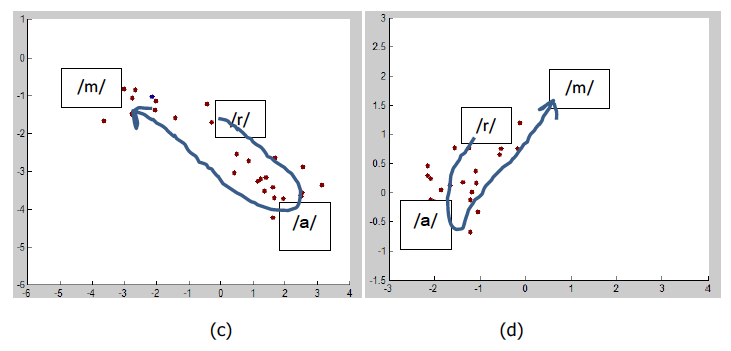

***I.***

Create scatter plots of the MFCCs computed in part ***H***. Use the MATLAB command `scatter()` to create the X-­Y scatter plots, for instance `scatter(MFCC(1,:),MFCC(2,:))` to plot the first and second MFCC. Try scatter plots in which you combine different MFCCs. 

***Answer:***

Which combination gives the best distinguishability of the individual phonemes?

***Answer:***

***J.***

Load the speech file “`data/wordraam.wav`” into MATLAB, plot the speech signal, and listen to the speech. Compute the MFCCs and make scatter plots of the MFCCs like in part ***I***. 

***Answer:***

Can you point out the MFCCs that belong to the three phonemes?

***Answer:***

***K.***

Record your own voice$^{(3)}$ while clearly pronouncing the phonemes of a word one-­by-­one (like in the sample speech file “`data/phonemesraam.wav`”). Compute the MFCCs and make scatter plots. 

$^{(3)}$*To record a speech fragment, use your laptop’s/computer’s microphone, or use a smartphone app like voice recorder.*

***Answer:***

Can you identify the cluster of MFCCs that belong to a particular phoneme? 

***Answer:***

Also record a complete word containing the phonemes you recorded earlier. Compute the MFCCs of the complete word. 

***Answer:***

Can you recognize the individual phonemes from the computed MFCCs?

***Answer:***